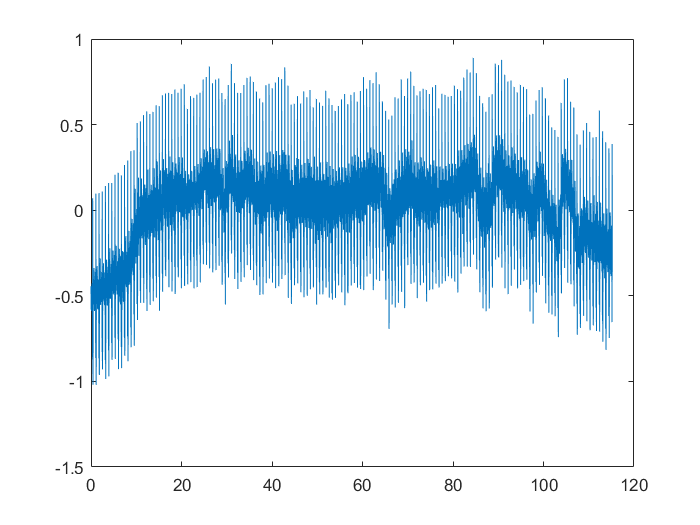

% Preprocessing ECG signal
% Sina Dabiri, 2021
[sig, Fs, tm] = rdsamp('ptbdb/patient001/s0014lre', 1);
data = sig;
plot(tm, sig);

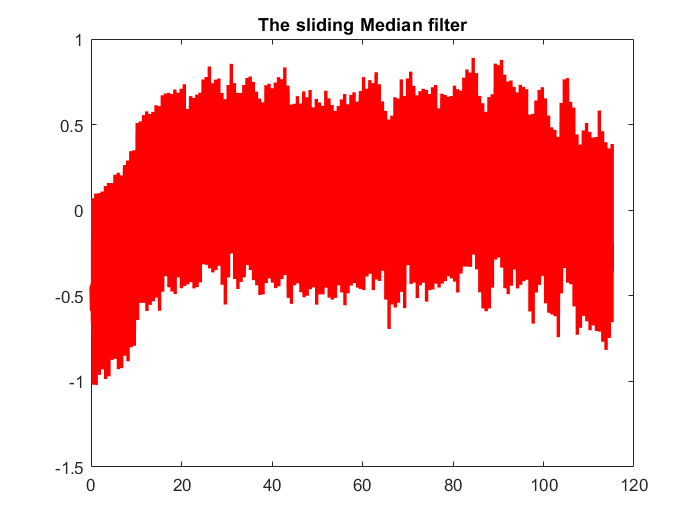

hold on
plot(tm, sig, 'b-');
% 'md' with wlen=0.2 sec
wlen = 200;
b = BaseLine1(data, wlen,'md');

plot(tm, b, 'r-', 'LineWidth',2);
title("The sliding Median filter");
hold off

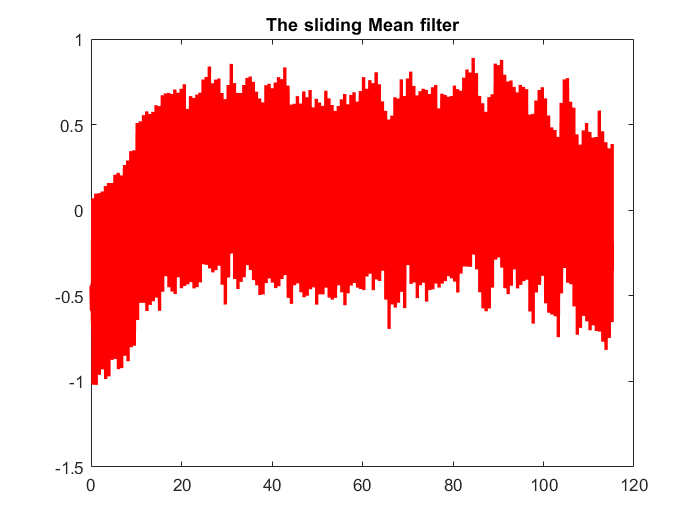

hold on
plot(tm, sig, 'b-');
% 'ma' with wlen=0.3 sec
wlen = 300;
b = BaseLine1(data, wlen,'mn');

plot(tm, b, 'r-', 'LineWidth',2);
title("The sliding Mean filter");
hold off